**Simple Pendulum Example**

syms th thdot thddot T real % Define some variables
syms m g l positive

% These will be useful:
state = [th;thdot]; % This is what ODE45 inputs to our function.
dstate = [thdot;thddot]; % This is what ODE45 expects to receive.

Make some unit vectors

% Good 'ole inertial frame
i = [1 0 0]'; j = [0 1 0]'; k = [0 0 1]'; 

% Polar coordinates
er = sin(th)*i - cos(th)*j;
eth = cos(th)*i + sin(th)*j;

**Kinematics**

Anchor point - 0, point location - p

% Positions
r_p_0 = l*er;

% Velocities
v_p_0 = jacobian(r_p_0,state)*dstate;

% Accelerations
a_p_0 = jacobian(v_p_0,state)*dstate

$$a\_p\_0 = \left(\begin{array}{c} l\,\mathrm{thddot}\,\cos\left(\mathrm{th}\right)-l\,{\mathrm{thdot}}^{2}\,\sin\left(\mathrm{th}\right)\\ l\,\cos\left(\mathrm{th}\right)\,{\mathrm{thdot}}^{2}+l\,\mathrm{thddot}\,\sin\left(\mathrm{th}\right)\\ 0 \end{array}\right)$$

**Newton time**

eqn = m*a_p_0 == -T*er + -m*g*j

$$eqn = \left(\begin{array}{c} m\,\left(l\,\mathrm{thddot}\,\cos\left(\mathrm{th}\right)-l\,{\mathrm{thdot}}^{2}\,\sin\left(\mathrm{th}\right)\right)=-T\,\sin\left(\mathrm{th}\right)\\ m\,\left(l\,\cos\left(\mathrm{th}\right)\,{\mathrm{thdot}}^{2}+l\,\mathrm{thddot}\,\sin\left(\mathrm{th}\right)\right)=T\,\cos\left(\mathrm{th}\right)-g\,m\\ 0=0 \end{array}\right)$$


[thdd,tension] = solve([eqn(1),eqn(2)],[thddot,T]);
thdd = simplify(thdd)

$$thdd = -\frac{g\,\sin\left(\mathrm{th}\right)}{l}$$

**Get the function prepared**

ln = 1; mn = 1; gn = 1; % Assign our constant values

dynamics = matlabFunction(thdd)

dynamics =     @(g,l,th)-(g.*sin(th))./l


odeFun = @(t,z)([z(2);dynamics(gn,ln,z(1))])

odeFun =     @(t,z)([z(2);dynamics(gn,ln,z(1))])



matlabFunction(thdd,'File','pendulumDyn'); % Let's also write to file for the next example.

**Integrate**

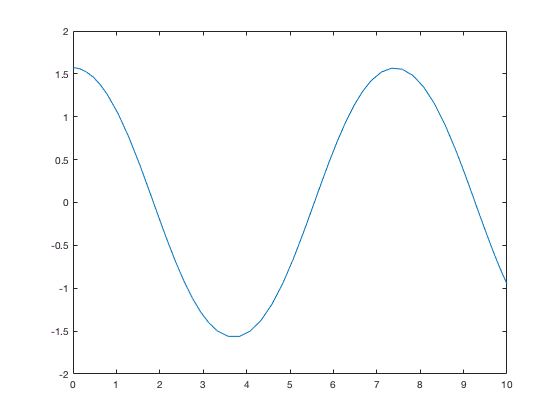

[tarray,zarray] = ode45(odeFun,[0 10],[pi/2,0]);

plot(tarray,zarray(:,1));